%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TempleNoisyclip1_Agra.wav');

player = audioplayer(samples, fsample);
play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples; %Samples, right and left channel

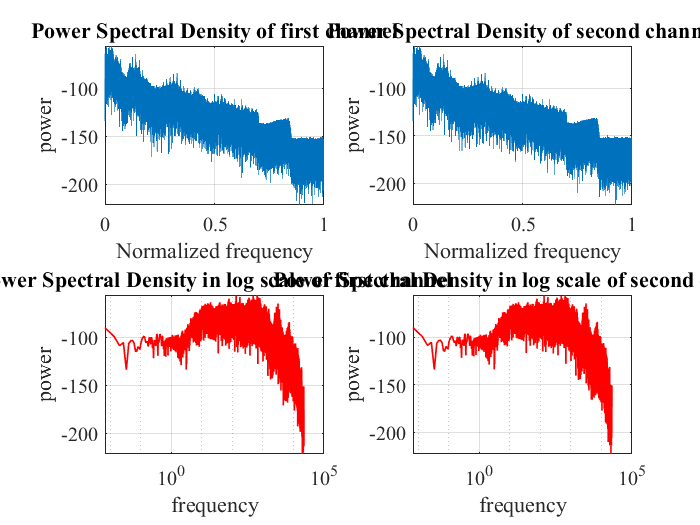

% PSD Show

ShowPSD(samples, fsample);

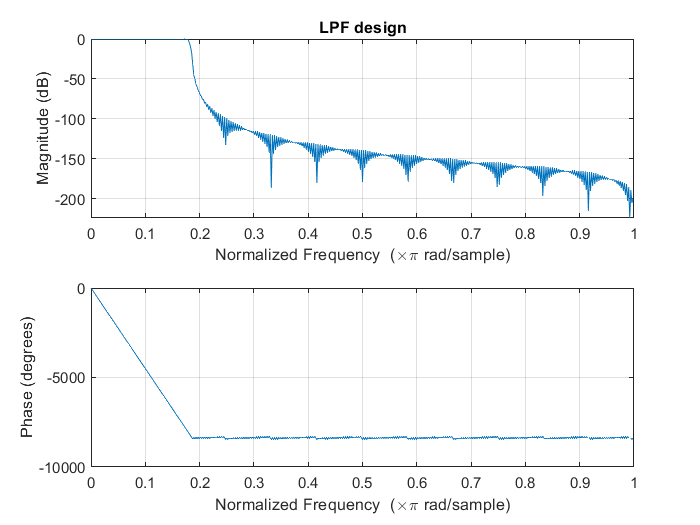

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




% player = audioplayer(NewSample, fsample);
% play(player);


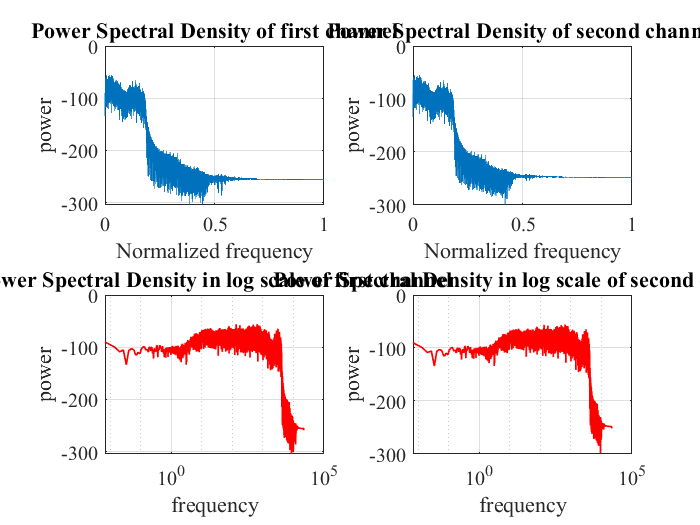

% PSD view
ShowPSD(NewSample, fsample);

% Output = MMSESTSA84(NewSample, fsample);

% player = audioplayer(Output, fsample);
% play(player);


a= rand(1, 44100);

W= ceil(0.032*44100)

W = 1412

Window = hamming(W);
overlappPerc=0.75;
sp = 1-overlappPerc

sp = 0.2500


Window=Window(:);
a1= NewSample(:, 1)';
L=length(a1);

SP=fix(W.*sp);

N=fix((L-W)/SP +1); %number of segments

repmat(1:W, N, 1);
repmat((0:(N-1))'*SP,1,W);
Index=(repmat(1:W,N,1)+repmat((0:(N-1))'*SP,1,W))'

Index =            1         354         707        1060        1413        1766        2119        2472        2825        3178        3531        3884        4237        4590        4943        5296        5649        6002        6355        6708        7061        7414        7767        8120        8473        8826        9179        9532        9885       10238       10591       10944       11297       11650       12003       12356       12709       13062       13415       13768       14121       14474       14827       15180       15533       15886       16239       16592       16945       17298
           2         355         708        1061        1414        1767        2120        2473        2826        3179        3532        3885        4238        4591        4944        5297        5650        6003        6356        6709        7062        7415        7768        8121        8474        8827        9180        9533        9886       10239       10592       10945       

hw=repmat(Window,1,N);
Seg=a1(Index);
Seg=a1(Index).*hw;

Seg

Seg =          0    0.0000    0.0000   -0.0000   -0.0000    0.0010    0.0013    0.0001   -0.0005   -0.0003   -0.0007    0.0007    0.0014    0.0042    0.0018    0.0001    0.0001    0.0005   -0.0005    0.0001    0.0004    0.0006   -0.0015   -0.0051   -0.0033   -0.0001   -0.0011    0.0004    0.0027    0.0004   -0.0037    0.0007    0.0004   -0.0031    0.0028   -0.0180    0.0027    0.0027    0.0014    0.0052    0.0004   -0.0040   -0.0046   -0.0011   -0.0039   -0.0029    0.0011    0.0002    0.0022    0.0046
         0   -0.0000    0.0000   -0.0000   -0.0000    0.0010    0.0012    0.0001   -0.0005   -0.0004   -0.0007    0.0007    0.0014    0.0043    0.0017    0.0001   -0.0000    0.0005   -0.0003    0.0001    0.0005    0.0005   -0.0014   -0.0050   -0.0034   -0.0000   -0.0011    0.0005    0.0030    0.0003   -0.0037    0.0005    0.0003   -0.0030    0.0027   -0.0177    0.0032    0.0027    0.0014    0.0050    0.0002   -0.0043   -0.0046   -0.0010   -0.0040   -0.0029    0.0012    0.0003    0.0025   

% Framing of the sample values
conSampleLength = 0.032

conSampleLength = 0.0320

WinLen = ceil(conSampleLength*fsample);
overlappPerc = 0.75;

[frame1, frame2]= Framing(NewSample,WinLen, overlappPerc, 1)

frame1 =          0    0.0000    0.0000   -0.0000   -0.0000    0.0010    0.0013    0.0001   -0.0005   -0.0003   -0.0007    0.0007    0.0014    0.0042    0.0018    0.0001    0.0001    0.0005   -0.0005    0.0001    0.0004    0.0006   -0.0015   -0.0051   -0.0033   -0.0001   -0.0011    0.0004    0.0027    0.0004   -0.0037    0.0007    0.0004   -0.0031    0.0028   -0.0180    0.0027    0.0027    0.0014    0.0052    0.0004   -0.0040   -0.0046   -0.0011   -0.0039   -0.0029    0.0011    0.0002    0.0022    0.0046
         0   -0.0000    0.0000   -0.0000   -0.0000    0.0010    0.0012    0.0001   -0.0005   -0.0004   -0.0007    0.0007    0.0014    0.0043    0.0017    0.0001   -0.0000    0.0005   -0.0003    0.0001    0.0005    0.0005   -0.0014   -0.0050   -0.0034   -0.0000   -0.0011    0.0005    0.0030    0.0003   -0.0037    0.0005    0.0003   -0.0030    0.0027   -0.0177    0.0032    0.0027    0.0014    0.0050    0.0002   -0.0043   -0.0046   -0.0010   -0.0040   -0.0029    0.0012    0.0003    0.0025

frame2 =          0    0.0000    0.0000   -0.0000   -0.0000    0.0010    0.0013    0.0001   -0.0005   -0.0003   -0.0007    0.0007    0.0014    0.0042    0.0018    0.0001    0.0001    0.0005   -0.0005    0.0001    0.0004    0.0006   -0.0015   -0.0051   -0.0033   -0.0001   -0.0011    0.0004    0.0027    0.0004   -0.0037    0.0007    0.0004   -0.0031    0.0028   -0.0180    0.0027    0.0027    0.0014    0.0052    0.0004   -0.0040   -0.0046   -0.0011   -0.0039   -0.0029    0.0011    0.0002    0.0022    0.0046
    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0010    0.0012    0.0001   -0.0005   -0.0004   -0.0007    0.0007    0.0014    0.0043    0.0017    0.0001   -0.0000    0.0005   -0.0003    0.0001    0.0005    0.0005   -0.0014   -0.0050   -0.0034    0.0000   -0.0011    0.0005    0.0030    0.0003   -0.0037    0.0005    0.0003   -0.0030    0.0027   -0.0177    0.0032    0.0027    0.0014    0.0050    0.0002   -0.0043   -0.0046   -0.0010   -0.0040   -0.0029    0.0012    0.0003    0.0025


% Fourier transform of the framed part
FSAMPLE1 = fft(frame1);
FSAMPLE2 = fft(frame2);



F = FSAMPLE1(1:fix(end)+1, :)

Error using fix
Not enough input arguments.